# Evaluación 11.1 (Trayectorias en lazo abierto)

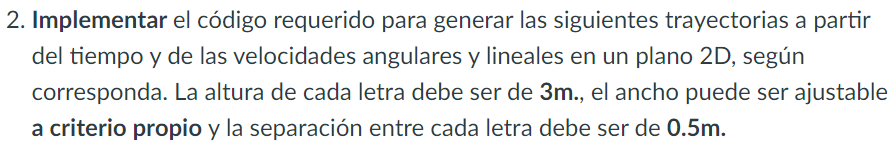

Responder las siguientes preguntas en base al procedimiento empleado para obtener las trayectorias propuestas:

- **a) **¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria recta? ¿Porqué?

Para obtener trayectorias rectas modifique parametros como la velocidad angular y lineal, así como el tiempo de muestreo, de esta manera es recorrido sería más preciso y el robot no tardaría tanto dando vueltas, debido a que la velocidad angular es 12 veces mayor a la lineal

- **b)** ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria curva? ¿Porqué?

La velocidad angular, esta debe ser un poco mayor a la lineal para obtener curvas, dependiendo del siguiente waypoint

- **c) **¿Cuál fué el o los parámetros que se modifican para obtener un giro? ¿Porqué?

Para los giros que se requieran que sean cerrados, es decir, inmediatos, la velocidad angular debe ser mucho mayor a la lineal

- **d) **¿Qué papel desempeña el vector del tiempo en la generación de la trayectoria?

El vector de tiempo, es para realizar todas las muestras y poder realizar la traycetoria, entre más waypoints tenga, se necesitan más muestras y por lo tanto más tiempo, el cual se modifica en el vector de tiempo.

- **e) **¿Cuáles fueron los parámetros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?

Primero los waypoints, todos los puntos necesarios para la trayectoria, de igual manera se modifico el punto de inicio, el vector de tiempo y la velocidad angular y lineal, para obtener los giros requeridos.

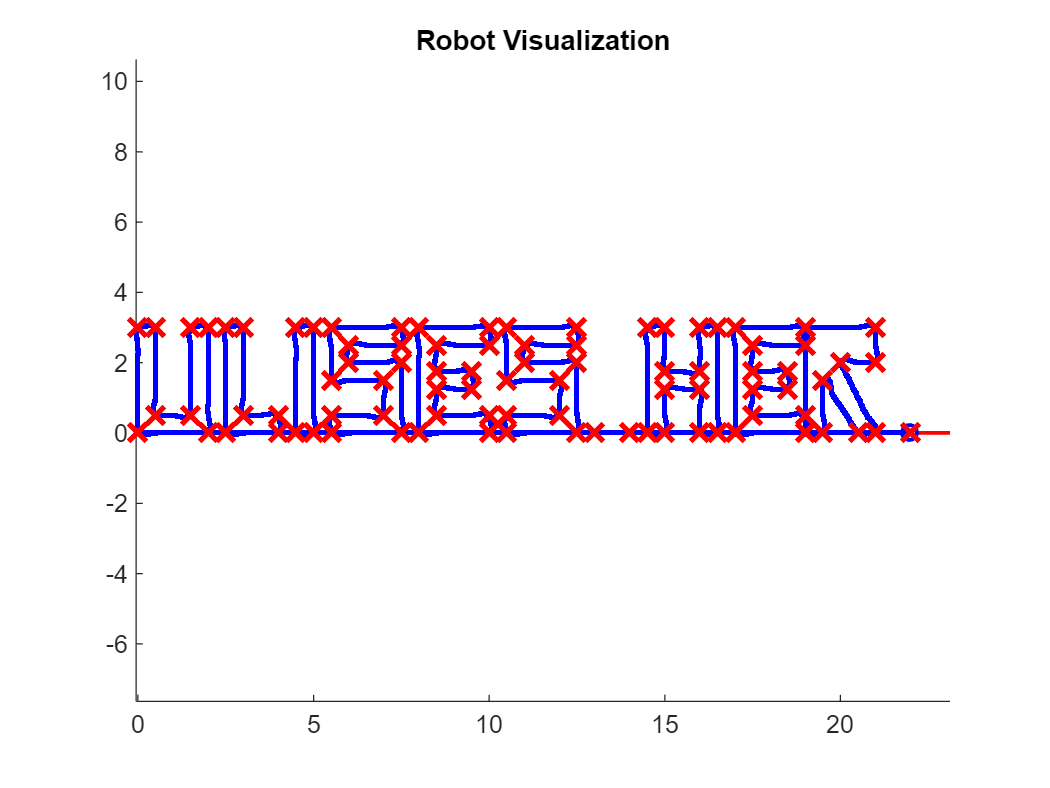

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:143;         % Time array

initPose = [0;0;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [0,0; 2,0; 2,3; 1.5,3; 1.5,0.5; 0.5,0.5; 0.5,3; 0,3; 0,0; %U
    2.5,0; 4,0; 4,0.5; 3,0.5; 3,3; 2.5,3; 2.5,0; 4.5,0; %L
    5,0; 5,3; 4.5,3; 4.5,0; 5.5,0; %I
    7.5,0; 7.5,2; 6,2; 6,2.5; 7.5,2.5; 7.5,3; 5.5,3; 5.5,1.5; 7,1.5; 
    7,0.5; 5.5,0.5; 5.5,0; %S
    8,0; 10,0; 10,0.5; 8.5,0.5; 8.5,1.25; 9.5,1.25; 9.5,1.75; 8.5,1.75; 8.5,2.5; 10,2.5; 
    10,3; 8,3; 8,0; %E
    10.5,0; 12.5,0; 12.5,2; 11,2; 11,2.5; 12.5,2.5; 12.5,3; 10.5,3; 10.5,1.5; 12,1.5; 
    12,0.5; 10.5,0.5; 10.5,0; %S
    13,0; 14,0; %Guion
    14.5,0; 15,0; 15,1.25; 16,1.25; 16,0; 16.5,0; 16.5,3; 16,3; 16,1.75; 
    15,1.75; 15,3; 14.5,3; 14.5,0; %H
    17,0; 19,0; 19,0.5; 17.5,0.5; 17.5,1.25; 18.5,1.25; 18.5,1.75; 17.5,1.75; 17.5,2.5; 19,2.5; 
    19,3; 17,3; 17,0; %E
    19.5,0; 19.5,1.5; 20.5,0; 21,0; 20,2; 21,2; 21,3; 19,3; 19,0; 22,0]; %R 

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.2;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 12;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end